clc
clear


## Import:* noisy_process.mat*

% Load variables
noisy_process = load("G:\My Drive\PhD\denoise_oxford\run_7\noisy_process.mat");
process_quadrant2 = noisy_process.process_quadrant;
clear noisy_process;

% Display results
process_quadrant2

process_quadrant2 = process_quadrant2(:,:,1) =

   1.0e-06 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0303         0         0         0         0         0    0.0303         0    0.0303         0         0         0         0    0.0303         0         0         0    0.0303         0         0         0         0         0         0         0         0         0    0.0303         0         0         0         0    0.0303         0    0.0606         0    0.0303         0         0    0.0303         0         0         0    0.0303         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0303         0         0         0         0    0.0303
         0         0         0       

input_check = process_quadrant2;
clear process_quadrant2


## Import: *results_process.mat*

% Load variables
results_process = load("G:\My Drive\PhD\denoise_oxford\run_7\results_process.mat");
results2 = results_process.results;
clear results_process;

% Display results
results2

results2 = struct with fields:
          input: [2×90×90 double]
    predictions: [2×90×90 single]
     validation: [2000×90×90 double]


results = results2;
clear results2


## Permute and reconstruct images

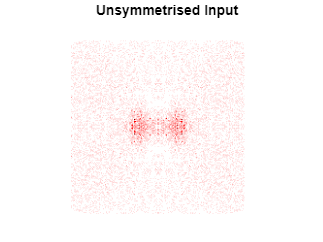

network_output = results.predictions;
network_output = permute(network_output, [2, 3, 1]);

network_input = results.input;
network_input = permute(network_input, [2, 3, 1]);


% unsymmetrised
network_input_full = flipcat_4fold_bl(network_input(:, :, 1));
showim(network_input_full, 1)
shading flat
title("Unsymmetrised Input")

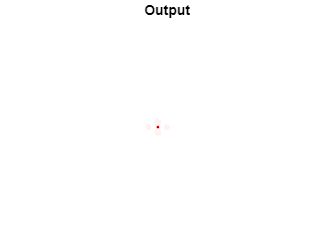


network_output_full = flipcat_4fold_bl(network_output(:, :, 1));
network_output_full = double(network_output_full);    % needed to save files properly
showim(network_output_full, 1)
title("Output")

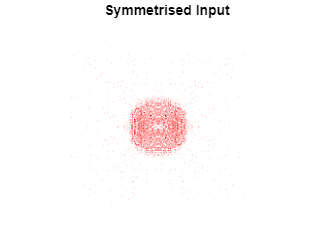



% symmetrised
network_input_full_sym = flipcat_4fold_bl(network_input(:, :, 2));
showim(network_input_full_sym, 1)
shading flat
title("Symmetrised Input")

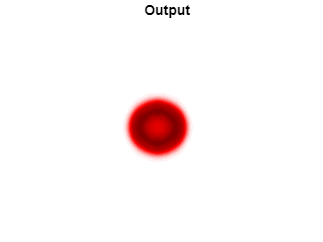


network_output_full_sym = flipcat_4fold_bl(network_output(:, :, 2));
network_output_full_sym = double(network_output_full_sym);    % needed to save files properly
showim(network_output_full_sym, 1)
title("Output")

## Save 4 versions of each image

% unsymmetrised input
save I+_13eV_input.dat network_input_full -ascii

% unsymmetrised output
save I+_13eV_output.dat network_output_full -ascii

% symmetrised input
save I+_13eV_input_symmetrised_NEW.dat network_input_full_sym -ascii

% symmetrised output
save I+_13eV_output_symmetrised_NEW.dat network_output_full_sym -ascii
